# Hyperbolic Equations

The focus of this chapter will be on hyperbolic equations and the analysis of various solution methods. Although their solutions are based on the same fundamental finite difference schemes introduced in the last teaching module, they have a contrasting behavior. Unlike parabolic equations, the solutions to hyperbolic equations are wave-like. Think of ocean waves propagating from point a to point b. They have some speed and frequency, and point b does not know the waves are approaching until they reach point b. As the wave is propagating, small disturbances like other waves can affect its speed or amplitude.  Actually, any perturbation will continuously propagate, which is unlike parabolic equations. The simplest hyperbolic equation is known as the 1D wave equation(linear advection equation) and is of the form:


$$\frac{\partial u}{\partial t} = a \frac{\partial u}{\partial x}$$


Before getting into how to solve this PDE with FDM, let's build an intuitive understanding of the equation.

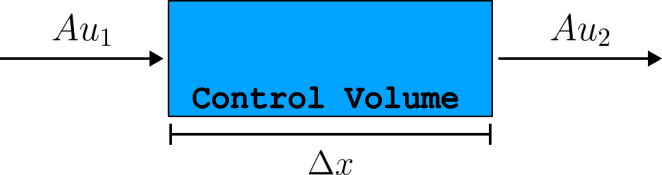

Imagine there is some amount of fluid entering the pipe above(control volume) and that pipe only has one inlet and one outlet. If we look at a small section of this pipe of size $\Delta x$, all of the fluid entering must also leave. The mass flow through any surface of the cube should be(density of the fluid $\rho$) x(velocity of the fluid normal to the face $U_n$) x(area of the face $ds$):


$$\rho U_n dS$$


To find the change in mass flux through the control volume:


$$A = \int_S \rho U dS = \rho U_2 \Delta y- \rho U_1 \Delta y$$


Now, consider the total mass inside the cube:


$$B = -\frac{\partial}{\partial t}\int_V \rho dV = -\frac{\partial \rho}{\partial t} A$$


Setting $A = B$, and simplifying:


$$\Delta y  (\rho U_2 - \rho U_1) =  -\frac{\partial \rho}{\partial t} A$$



$$\frac{\partial \rho U}{\partial x} = \frac{\partial \rho}{\partial t}$$


If $U$ is constant:


$$U\frac{\partial \rho }{\partial x} = \frac{\partial \rho}{\partial t}$$


This form of the equation is regarded as the 1D linear advection equation. There is some quantity, in this case $\rho$, being transported at some speed $U$. It's also known as the transport equation. Another example is the transportation of pollen in the air. The pollen has very little affect on the velocity of the air, but travels with the flow. The two-way wave equation can be derived by taking the derivative of both sides of the linear advection equation:


$$\frac{\partial}{\partial x}(U\frac{\partial \rho }{\partial x}) = \frac{\partial}{\partial x}\frac{\partial \rho}{\partial t}$$



$$\frac{\partial^2 \rho}{\partial t^2} = U^2 \frac{\partial^2 \rho}{\partial x^2}$$


## Learning objectives

- Direction dependent difference schemes

- Stability requirement

- Dispersion relation

## 1D Wave equation

As an example, let's begin by solving the 1D wave equation with the following boundary and initial conditions:

- 
$$u(t, 0) = u(t, 2\pi), t \in [0, \infty]$$


- 
$$u(0,x) = \sin(x) \text{ for } t=0, x \in [0,1]$$


To solve the PDE, let's use the forward Euler method in time and a first order forward difference in space. We will also solve it for two different wave speeds.

- 
$$a =1$$


- 
$$a = -1$$



$$\frac{u_j^{i+1} - u_j^i}{\Delta t} = a\frac{u_{j+1}^i - u_j^i}{\Delta x$$


A crucial difference between the wave equation and the diffusion equation is the treatment of the boundary condition. In the last teaching module we had Dirichlet boundary conditions. However, in this case, the boundary condition is periodic. The boundary points at $x=0$ and $x=2\pi$ are not fixed, but are set equal to each other:

**Periodic boundary condition for forward difference scheme**

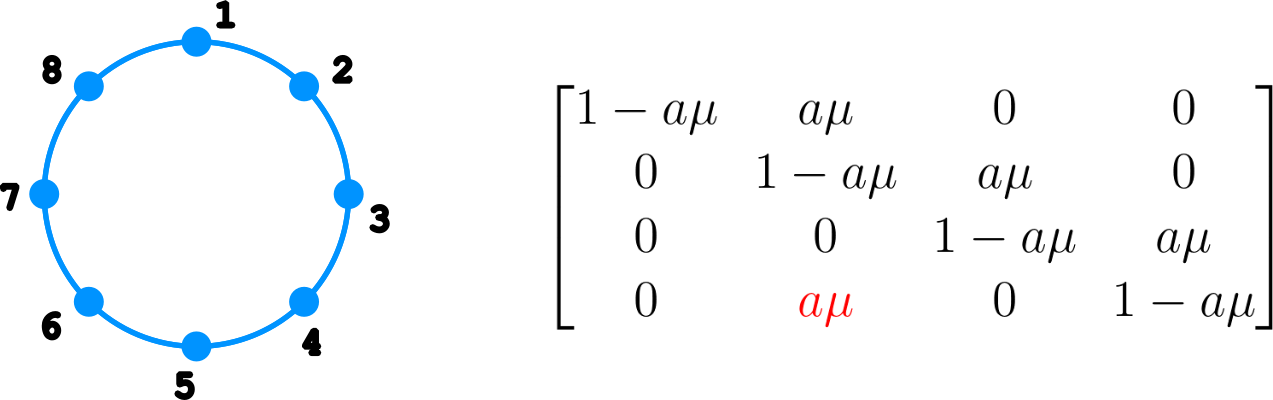

In the above figure, the circle represents the relationship between the points in the domain and the boundary points. Point 1 represents the value of $u$ at both $x=0$ and $x=2\pi$. To account for this in the matrix an additional term is added in red. Let's write the matrix multiplication explicitly to better visualize how this works:


$$u_j^{i+1} = a\lambda u_{j+1}^i + (1 - a\lambda)u_j^i \\
u_1^2 = a\lambda u_2^1 + (1 - a\lambda)u_1^1 \\
u_2^2 = a\lambda u_3^1 + (1 - a\lambda)u_2^1 \\
... \\
u_N^{2} = a\lambda u_{N+1}^i + (1 - a\lambda)u_N^i \\$$


When solving for point $N$, point $N+1$ is needed. If point $N = u_1$ this makes point $N+1 = u_2$, which is why the extra term is included in the matrix. Using this scheme and solving the two cases, the following two solutions are obtained:

**1D wave equation solution for **$a=1$

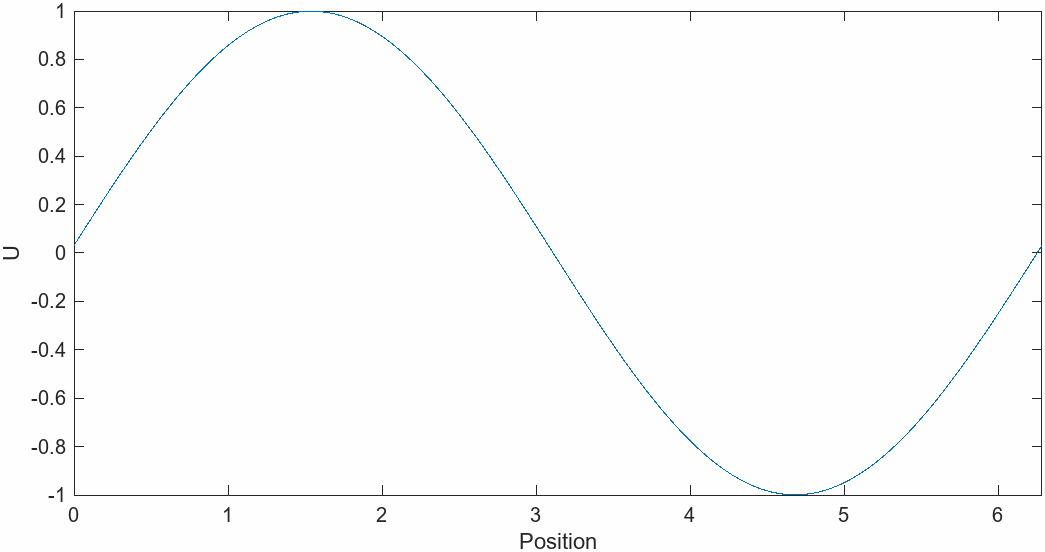

**1D wave equation solution for **$a=-1$

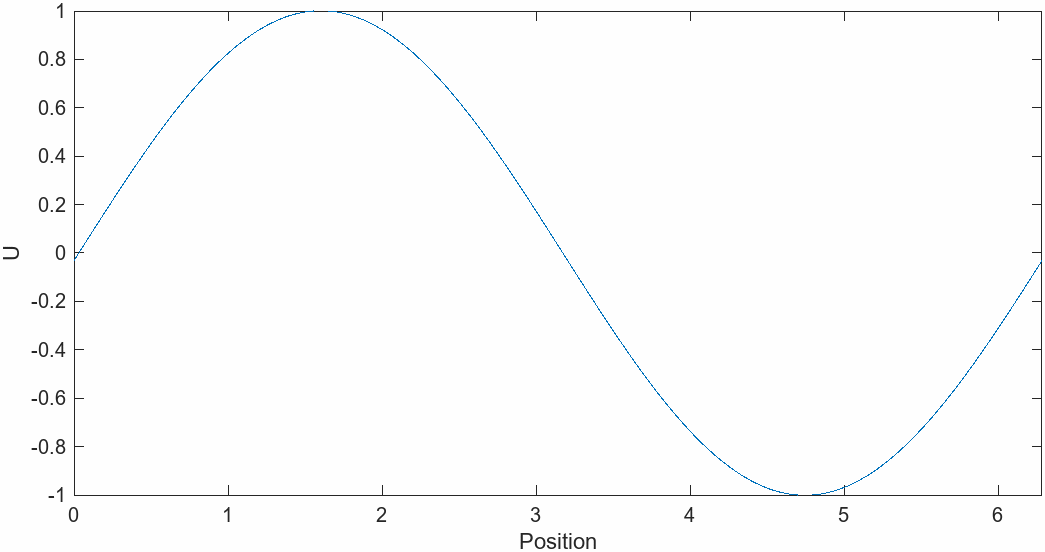

In the first case, where $a=1$, the solution is stable, but the wave's amplitude is decaying. In the second case, where $a=-1$, the wave is propagating in the opposite direction, but blows up. Both cases use the exact same method, so **why is one stable and the other unstable? **Run the following code, and perform the exercise yourself. Try to answer the following questions, before moving on to the next section.

- Where does the difference in amplitude arise between the numerical and exact solution?

- On line $11$ change the formula for the timestamp to be$\Delta t = |\Delta x a|$. How did this change the solution?

- Change the wave speed to $a=-1$. What is different about this solution?

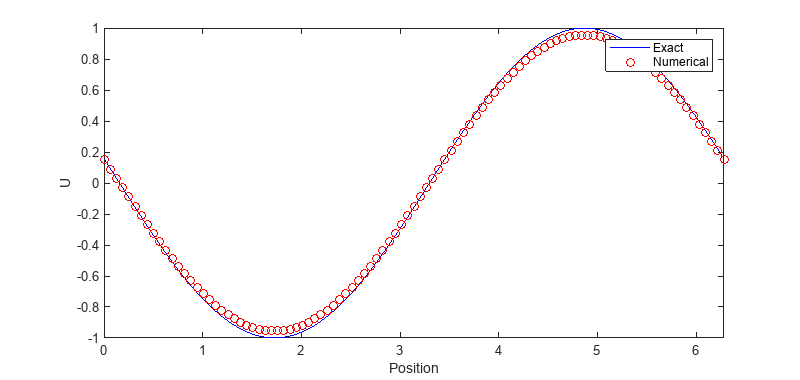

% Define the parameters
L = 2*pi;          % Length
T = 3;             % Total time
N = 100;           % Number of spatial grid points
a = 1;             % Wave speed

% Spatial discretization
dx = L/N;

% Stability condition
dt = abs(dx/a)*0.5;

% Number of iterations
M = int32(T/dt);

% Spatial grid
x = linspace(0,L,N+1);

% Initialize the temperature matrix
u = zeros(N+1,1);

% Set the initial condition
u(:,1) = sin(x);

% Building the matrix
D = ones(N+1,1)*(1 - a*dt/dx);
D1 = ones(N,1)*a*dt/dx;

A = diag(D) + diag(D1,1);
A(end,2) = A(1,2);

% Apply the finite difference method
figure;
for j = 1:M
    u = A*u;
end

% Exact solution
exact = sin(x + a*double(M)*dt);

% Plotting
figure
plot(x,exact,'b') 
hold on
plot(x,u,'ro')

xlabel("Position")
ylabel("U")
legend("Exact","Numerical")
set(gcf,'Position',[0 0 800 380])

ylim([-1 1])
xlim([0 2*pi])

## Stability

Let's address the instability seen when there is a negative wave speed. To do so, we can perform a von Neumann Stability analysis and substitute $u_j^i =  \Lambda^m e^{ikn\Delta x}$ into the difference:


$$\frac{\Lambda^{m+1}e^{ikn\Delta x} - \Lambda^me^{ikn\Delta x}}{\Delta t} = a \frac{\Lambda^m e^{ik(n+1)\Delta x} - \Lambda^m e^{ikn\Delta x}}{\Delta x}$$


Now divide both sides by $\Lambda^m e^{ikn\Delta x}$ and multiply both sides by $\Delta t$, using $\lambda = \frac{\Delta t}{\Delta x}$:


$$\Lambda - 1 = a \lambda (e^{ik\Delta x }- 1)$$


Using Euler's equation, we can substitute the exponential terms for sine and cosine:


$$\Lambda - 1 = a\lambda( \cos(\theta) + i\sin(\theta) - 1)$$


To satisfy the stability criteria, $|\Lambda| < 1$:


$$|\Lambda| = \sqrt {(1 + a\lambda \cos(\theta) - a\lambda)^2 + a^2\lambda^2 \sin^2(\theta)}$$


Simplifying the expression:


$$|\Lambda| = 1 + 2a\lambda (\cos(\theta) - 1)(1-a\lambda)$$



$$|\Lambda| = 1 -4a\lambda\sin^2(\frac{\theta}{2})(1-a\lambda) \leq 1$$


There are two possible scenarios for the above equation depending whether $a=1$ or of $a=-1$. If $a=1$, the above equation has three terms:$1$, $-4a\lambda\sin^2(\frac{\theta}{2})$, and $(1-a\lambda)$. If, $a$ is positive, this guarantees the third term must also be positive in order to satisfy the condition. One minus a positive number multiplied by a positive number will guarantee the stability criterion for this case. So we have to ensure the third term must be positive:


$$1-a\lambda \geq 0$$



$$\lambda \leq \frac{1}{a}$$


In this case, the finite different scheme is **conditionally stable** if the above condition is true. What about the case  when $a$ is negative? Well, if $a=-1$, the third term must be negative in order to satisfy the stability criteria:


$$1+|a|\lambda \leq 0$$



$$\lambda \leq \frac{-1}{|a|}$$


Here, we see the scheme is **unconditionally unstable** for any value of $a \leq 0$. This means, there is no criteria which will guarantee a stable solution using the forward difference scheme if $a$ is negative. Clearly, hyperbolic equations are more sensitive to the difference schemes used when compared to parabolic, but why? Let's first find the stability criteria for a central difference scheme before drawing any conclusions.


$$\frac{u_j^{i+1} - u_j^i}{\Delta t} = a \frac{u_{j+1}^i - u_{j-1}^i}{2\Delta x}$$


Following the same substitution as before:


$$\frac{\Lambda^{m+1}e^{ikn\Delta x} - \Lambda^me^{ikn\Delta x}}{\Delta t} = a \frac{\Lambda^m e^{ik(n+1)\Delta x} - \Lambda^m e^{ik(n-1)\Delta x}}{2\Delta x}$$


Simplifying the above equation:


$$\Lambda - 1 =\frac{a\lambda}{2}(e^{ik\Delta x} - e^{-ik\Delta x})$$


Applying Euler's equation:


$$\Lambda = \frac{a\lambda}{2}(2i\sin(\theta)) + 1$$



$$|\Lambda| = \sqrt{1 + a^2 \lambda^2\sin^2(\theta)}$$


The above equation is also** unconditionally unstable**. There is no criteria on $\lambda$ for any positive or negative $a$ which will guarantee $|\Lambda| \leq 1$. This brings us back to the main question: why is the stability limit so stringent and so heavily dependent on the sign of $a$? Well,  let's take a step back and think more intuitively about the problem. We are solving the 1D wave equation, and the propagation of the waves direction depends on the sign of $a$. When $a$ is positive the wave propagates in the negative x direction and is conditionally stable. When $a$ is negative it propagates in the positive x direction and is unconditionally unstable. It seems that the direction of information has some bearing on stability. In the forward difference scheme we are using points at $j$ and $j+1$. When $a=1$, information propagates from right to left, so using information from $j+1$ makes sense. When $a=-1$, information is propagating from left to right, but we are still using $j+1$ points, to calculate a value for $j$. **Does this make sense?**

There is also an additional reason why the solution is unstable. In the previous code, run the solution for 1 time-step for both $a=1$ and $a=-1$. Calculate the maximum value of the solution $u$. It turns out the wave amplitude is decreasing when $a$ is positive, and the amplitude is increasing when $a$ is negative. This is due to **dispersion**. When the stability condition is satisfied, the eigenvalues of our solution are going to be less than one, and the solution is going to be damped. Typically,  in non-linear problems, this dampening is sometimes necessary to prevent instability. However, when $\lambda > 1$the eigenvalues are greater than one, which eventually cause the solution to blow up.

**Finite difference schemes and their stability limit**

## Dispersion

To understand dispersion let's look at the solution to the 1D wave equation with the following initial condition:


$$u(0,x) = \begin{cases} 1 ,&\text{ if } 0.3 < x < 0.7\\ 0,& \text{ otherwise}\end{cases}$$


This wave is discontinuous at points 0.3 and 0.7. This will cause finite difference schemes to over/undershoot when computing the derivative. If we solve the wave equation using the forward difference and Lax-Wendroff scheme, the following figure shows the solution.

**Finite difference solution for two different schemes**

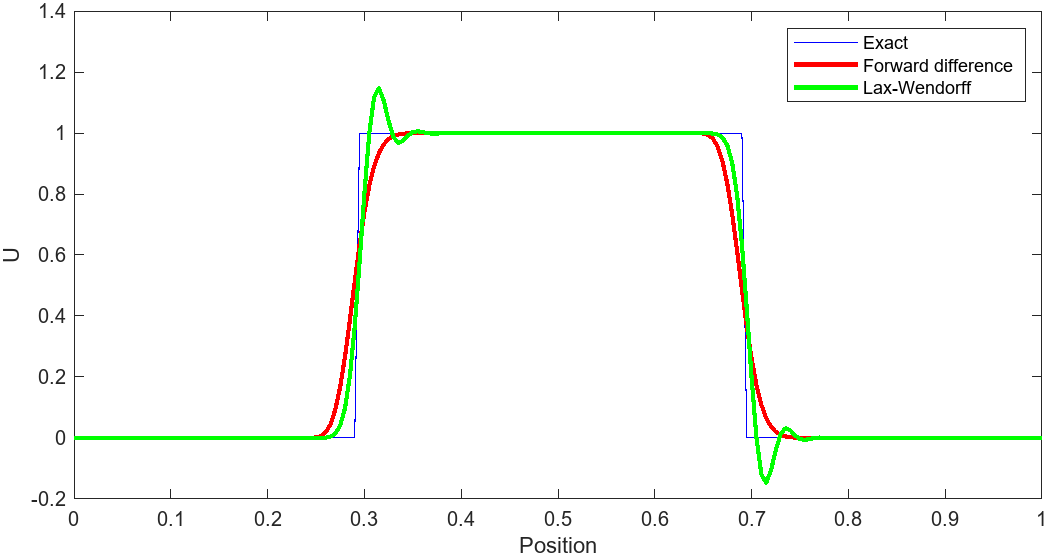

As you can see, Lax-Wendroff has overshot the discontinuities. These oscillations are are a result of differences between the numerical and exact dispersion relation, where dispersion is defined as the propagation of waves at different speeds and wave lengths. To understand this, let's look at an analytical solution and compare it to the numerical. We begin with the assumption that the analytical solution will look something like $u(t,x) = f(t) e^{ikx}$. Plugging this into the wave equation and simplifying:


$$\frac{\partial u}{\partial t} + a \frac{\partial u}{\partial x} = 0$$



$$\frac{\partial f}{\partial t}e^{ikx} + a f(t)ike^{ikx} = 0$$



$$\frac{\partial f}{\partial t} = -iakf(t)$$


Here we see that a derivative is equal to some constant multiplied by itself. We can infer that it is an exponential. Integrating the expression gives:


$$f(t) = f(0)e^{-iakt}$$


Plugging this into our original assumption:


$$u(t,x) = f(0) e^{-iakt}e^{ikx}$$



$$=f(0)e^{ik(x-at)}$$



$$w = ka$$


In the above equation, this is the dispersion relation for the analytical solution. In other words, it is not dispersive; the wave speed $a$ is independent of the wave number $k$ and independent of frequency $w$. The wave number $k$ is the number of waves in a period before the function repeats itself, and phase speed $a$ is the rate at which the wave is propagating. Let's perform the same analysis, but using the centered difference approximation for the spatial derivative:


$$\frac{\partial f}{\partial t}e^{ikj\Delta x} = -af\frac{e^{ik(j+1)\Delta x} - e^{-ik(j-1)\Delta x}}{2\Delta x}$$



$$\frac{\partial f}{\partial t}=  \frac{-af}{2\Delta x} (e^{ikj\Delta x} - e^{-ikj\Delta x})$$


Using Euler's equation to replace the exponential terms:


$$\frac{\partial f}{\partial t} = \frac{-af}{2\Delta x}(2i \sin(k\Delta x)$$



$$ = \frac{-af}{\Delta x}(i \sin(k\Delta x)$$


Let's also use the following notation $k^* = \frac{\sin(k\Delta x)}{\Delta x}$ to simplify the expression:


$$f(t) = f(0)e^{-iak^*t}$$



$$u(t,x) = f(0) e^{-iak^*t}e^{ikx}$$



$$=f(0) e^^{-ik(x - \frac{ak^* t}{k})}$$


Lets simplify the expression using $a^* = \frac{ak^*}{k}$


$$u(t,x) = f(0)e^{ik(x-a^*t)}$$



$$w = ka^* = a\frac{\sin(k\Delta x)}{k \Delta x}$$


Now the dispersion relation depends on $a^*$ which depends on $k^*$. Instead of having an exact wave number, the solution now depends on a modified wave number, which has grid dependence. So, if the wave number of the simulation was $k=1$ and $\Delta x=1$, the modified wave number would be $k^* = 0.998$. This is relatively close to the exact wave number,  but if $k=10$, the modified wave number is $k^*=8.415$. If the solution of the PDE is needed far ahead in time,  it may not be comparable to the exact. In order to minimize the effect of dispersion a small $\Delta x$ must be used at large wave numbers. 

**Fully discrete dispersion relations**

##  Exercise 1

Calculate the local truncation error and perform a stability analysis for the two-way wave equation using a central difference scheme in time and in space. Note that a centered difference in time scheme, uses three time level solutions: $u^{i+1}, u^i, u^{i-1}$. 


$$\frac{\partial^2 u}{\partial t^2} = a^2 \frac{\partial^2 u}{\partial x^2}$$


% open("exercise/hyperbolic_ex1.m")

Use the following boundary and initial conditions:

- 
$$u(t, 0) = u(t, 2\pi) = 0, t \in [0, \infty]$$


- 
$$u(0,x) = \sin(x) \text{ for } t=0, x \in [0,1]$$


- a = -1

- a = 1

Why does the wave propagation direction not affect the stability criteria in the two-way wave equation? 

**Next section:**

The final section in the finite difference teaching module course covers the solution of elliptic equations. Unlike parabolic and hyperbolic equations, elliptic equations are boundary value problems. Their solutions require either iterative methods or a direct solve of their matrix equation to find the solution. The following code opens the course on elliptic equations.

% open("ellipticEquations.mlx")